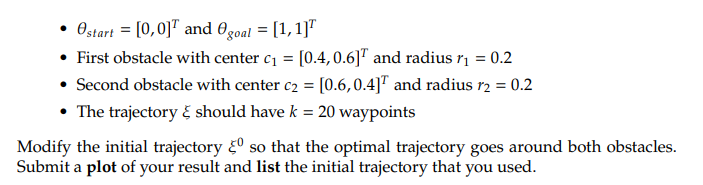

clear
clc
close all

% Start and Goal orientations
theta_start = [0;0];
theta_goal = [1;1];

% Initial trajectory variables
n = 2; % No. of joints/ 2-D trajectory
k = 20; % No. of waypoints

% Obstacles 1 and 2 parameters
% First obstacle's radius and center
r1 = 0.2;
center1 = [0.4;0.6];
% Second obstacle's radius and center
r2 = 0.2; 
center2 = [0.6;0.4];


% MY INITIAL TRAJECTORY
% Create initial trajectory that arches above the first and below the second obstacle
mid_point1 = [0.5; 0.7]; % A point above the first obstacle
mid_point2 = [0.5; 0.3]; % A point below the second obstacle

% Construct initial trajectory xi_0
xi_0 = [linspace(theta_start(1), mid_point1(1), floor(k/4)), ...
        linspace(mid_point1(1), mid_point2(1), floor(k/4)), ...
        linspace(mid_point2(1), theta_goal(1), floor(k/2));
        linspace(theta_start(2), mid_point1(2), floor(k/4)), ...
        linspace(mid_point1(2), mid_point2(2), floor(k/4)), ...
        linspace(mid_point2(2), theta_goal(2), floor(k/2))];
xi_0_vec = reshape(xi_0, [],1); % Reshape for the need of optimization

% Equality constraints for start and goal positions
A = [eye(n), zeros(n,n*(k-1)) ;...
    zeros(n,n*(k-1)), eye(n) ];

B = [theta_start;theta_goal];

% Nonlinear optimization
options = optimoptions('fmincon','Display','iter',...
    'Algorithm','sqp','MaxFunctionEvaluations',1e5);
xi_star_vec = fmincon(@(xi) cost(xi), xi_0_vec, ...
    [], [], A, B, [], [], [], options);

 Iter  Func-count            Fval   Feasibility   Step Length       Norm of   First-order  
                                                                       step    optimality
    0          41    5.259554e+03     0.000e+00     1.000e+00     0.000e+00     1.096e+05  
    1         105    4.223578e+03     0.000e+00     2.737e-04     4.063e+01     1.276e+02  
    2         148    3.412082e+03     0.000e+00     4.900e-01     5.225e+01     6.299e+01  
    3         192    3.360310e+03     0.000e+00     3.430e-01     3.162e+01     5.050e+01  
    4         235    2.233704e+03     0.000e+00     4.900e-01     4.734e+01     4.379e+01  
    5         277    2.038745e+03     0.000e+00     7.000e-01     4.050e+01     4.369e+01  
    6         319    1.634861e+03     0.000e+00     7.000e-01     3.146e+01     4.701e+01  
    7         361    1.474206e+03     0.000e+00     7.000e-01     2.980e+01     4.114e+01  
    8         403    1.231450e+03     0.000e+00     7.000e-01     2.418e+01     3.

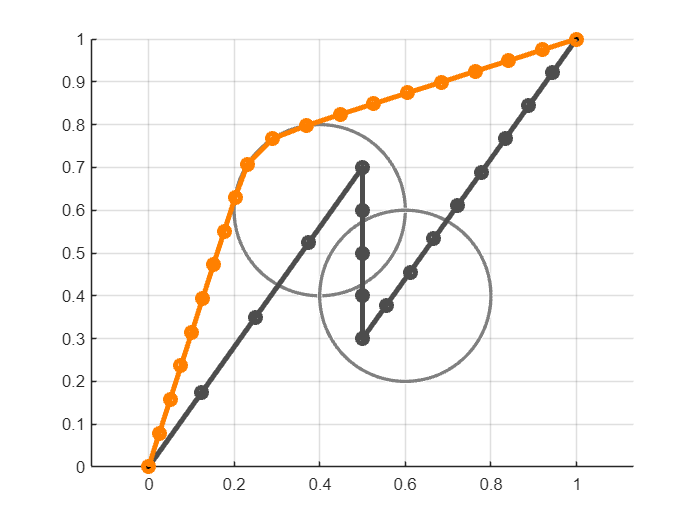


xi_star = reshape(xi_star_vec,2,[]); % final optimized trajectory

% Plot obstacles
figure
grid on
hold on
axis([0, 1, 0, 1])
axis equal
viscircles(center1', r1, 'Color', [0.5, 0.5, 0.5]);
viscircles(center2', r2, 'Color', [0.5, 0.5, 0.5]);
plot(0, 0, 'ko', 'MarkerFaceColor', 'k')
plot(1, 1, 'ko', 'MarkerFaceColor', 'k')

% Plot result
grid on
hold on
axis equal
plot(xi_0(1,:), xi_0(2,:), 'o-', 'Color', [0.3, 0.3, ...
 0.3], 'LineWidth', 3);
plot(xi_star(1,:), xi_star(2,:), 'o-',...
    'Color', [1, 0.5, 0], 'LineWidth', 3);


% Cost function to minimize

function C = cost(xi)
    gamma = 20; % Repulsion coefficient
    xi = reshape(xi, 2, []);
    C = 0;
    epsilon = 1e-6; % Small constant to prevent division by zero
    
    % Define obstacles with correct centers and radii
    obstacles = [
        0.4, 0.6, 0.2; % First obstacle
        0.6, 0.4, 0.2; % Second obstacle
        % Add more obstacles if needed
    ];
    
    for idx = 2:length(xi)
        Urep = 0;
        for obs = 1:size(obstacles, 1)
            center = obstacles(obs, 1:2)';
            r = obstacles(obs, 3);
            dist_to_center = norm(xi(:, idx) - center);
            
            % Calculate repulsive potential if within the obstacle's influence
            if dist_to_center < r
                % Add a small value epsilon to prevent division by zero
                Urep = Urep + 0.5 * gamma * ((1 / (dist_to_center + epsilon)) - (1 / r))^2;
            end
        end
        
        % Sum the repulsive potential and the path length cost
        C = C + norm(xi(:, idx) - xi(:, idx - 1))^2 + Urep;
    end
end


% MY INITIAL TRAJECTORY
% % Create initial trajectory that arches above the first and below the second obstacle
% mid_point1 = [0.5; 0.7]; % A point above the first obstacle
% mid_point2 = [0.5; 0.3]; % A point below the second obstacle
% 
% % Construct initial trajectory xi_0
% xi_0 = [linspace(theta_start(1), mid_point1(1), floor(k/4)), ...
%         linspace(mid_point1(1), mid_point2(1), floor(k/4)), ...
%         linspace(mid_point2(1), theta_goal(1), floor(k/2));
%         linspace(theta_start(2), mid_point1(2), floor(k/4)), ...
%         linspace(mid_point1(2), mid_point2(2), floor(k/4)), ...
%         linspace(mid_point2(2), theta_goal(2), floor(k/2))];